## **STAVOVÁ ROVNICE IDEÁLNÍCH PLYNŮ**

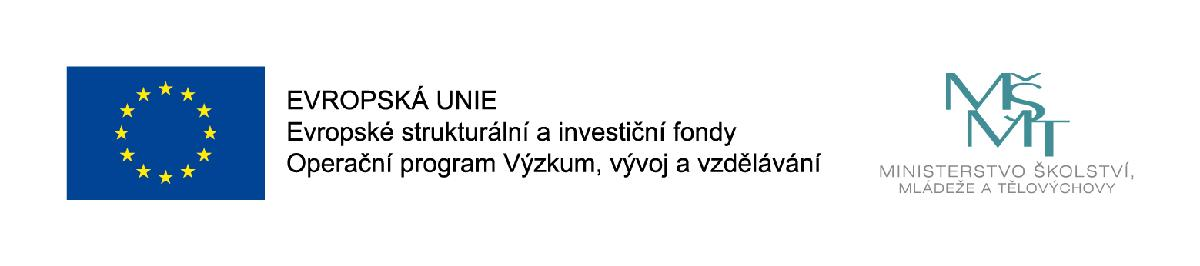

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

#### www: [http://bit.ly/termomechanika_online/](http://bit.ly/termomechanika_online/)

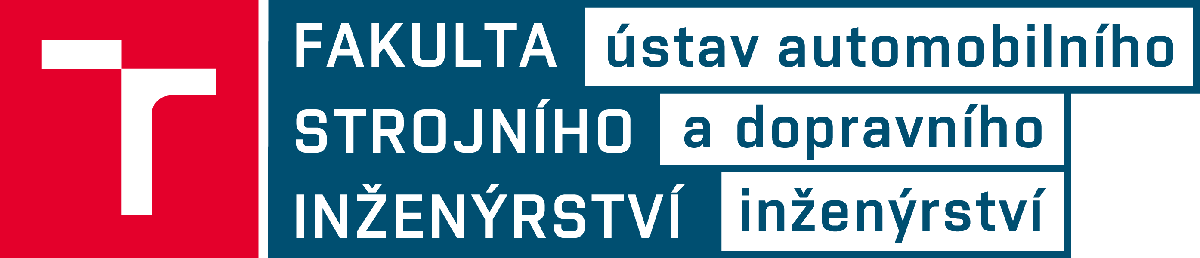

#### Tabulka vlastnosti ideálních plynů:

% Molarni hmotnost [kg/kmol]
% Poissonova konstanta [-]
% Pocet atomu v molekule [-]
% Merna plynova konstanta [J/kgK]
% Merna tepelna kapacita pri konstantnim tlaku [J/kgK]
% Merna tepelna kapacita pri konstantnim objemu [J/kgK]
RowName = {'Molarní hmotnost [kg/kmol]';'Poissonova konstanta [-]';'Počet atomů v molekule [-]';'Měrná plynová konstanta [J/kgK]';'Měrná tepelna kapacita pri konstantnim tlaku [J/kgK]';'Merna tepelna kapacita pri konstantnim objemu [J/kgK]'};

Ar=[39.948;1.667;1;208.1;520.0;312.0];
He=[4.003;1.667;1;2077;5198;3116];
H2=[2.02;1.409;2;4122.2;14209;10085];
Ne=[20.183;1.667;1;412;1020;618];
N2=[28.18;1.400;2;296.8;1042;745];
O2=[32.0;1.393;2;259.8;922;662];

Air=[28.97;1.4;2;287;1003;717];
H2O=[18.02;1.327;3;461.5;1872;1411];
NH3=[17.031;1.297;4;488.2;2130.0;1642.0];
CO2=[44.01;1.289;3;188.9;842.0;653.0];
CO=[28.01;1.400;2;296.8;1041;744];
NO=[30.006;1.387;2;277.1;993.0;716.0];
N2O=[44.013;1.274;3;188.9;879.0;690.0];
SO2=[64.059;1.263;3;129.9;624.0;494.0];
SO3=[80.053;1.196;4;103.86;635.0;531.0];

CH4=[16.043;1.299;5;518.3;2254.0;1736.0];
C4H10=[58.12;1.091;14;143.0;1716.0;1573.0];
C2H6=[30.07;1.186;8;276.5;1766.0;1490.0];
C2H4=[28.054;1.237;6;296.4;1548.0;1252.0];
C3H8=[44.094;1.126;11;188.6;1679.0;1490.0];
C8H18=[114.23;1.044;26;72.79;1711.0;1638.0];
C2H2=[26.038;1.231;4;319.3;1699.0;1380.0];
C2H6=[30.07;1.186;8;276.5;1766.0;1490.0];
CF3CH2F=[102.03;1.106;11;81.49;852.0;771.0];

%ta = table(RowName,Ar,Air,H2O)
IdealniPlyn1 = table(Ar,He,Ne,H2,N2,O2,Air,H2O,CO,CO2,'RowNames',RowName)
IdealniPlyn2 = table(NO,N2O,NH3,SO2,SO3,CH4,C4H10,C2H6,C2H4,C3H8,'RowNames',RowName)

### Příklad

Posluchárna P3 na FSI má rozměry 12×12×6 m3. Zjistěte, zda byste unesli tlakový zásobník (bombu) o objemu 50 litrů, který by obsahoval veškerý vzduch z této posluchárny (hmotnost zásobníku neuvažujte). Určete rovněž tlak v této bombě za dané teploty. Teplota v posluchárně je 22 °C a atmosférický tlak je 1000 hPa.

a = 12;             % [m]
b = 12;             % [m]    
c = 6;              % [m]
Vblitr = 50;        % [litr]
tC = 22;            % [°C]
pbhPa = 1000;       % [hPa]
V = a*b*c;          % [m^3]
r = 287.04          % [J/kgK]    
m = hPa2Pa(pbhPa)*V/(r*C2K(tC))    % [kg]
pbomba=Pa2MPa(m*r*C2K(tC)/l2m3(Vblitr))  % [MPa]

IdealniPlyn1 = 6×10 table
                                                               Ar       He        Ne        H2       N2       O2       Air      H2O      CO       CO2 
                                                             ______    _____    ______    ______    _____    _____    _____    _____    _____    _____

    Molarní hmotnost [kg/kmol]                               39.948    4.003    20.183      2.02    28.18       32    28.97    18.02    28.01    44.01
    Poissonova konstanta [-]                                  1.667    1.667     1.667     1.409      1.4    1.393      1.4    1.327      1.4    1

### Příklad

Jaká je hustota vzduchu, kyslíku, vodíku, zemního plynu a propanu při tlaku 1000 hPa a teplotě 20 °C?

phPa = 1000.0;    % [hPa]

IdealniPlyn2 = 6×10 table
                                                               NO       N2O       NH3       SO2       SO3       CH4      C4H10    C2H6      C2H4      C3H8 
                                                             ______    ______    ______    ______    ______    ______    _____    _____    ______    ______

    Molarní hmotnost [kg/kmol]                               30.006    44.013    17.031    64.059    80.053    16.043    58.12    30.07    28.054    44.094
    Poissonova konstanta [-]                                  1.387     1.274     1.297     1.263     1.196     1.299    1.091    1

tC   = 20.0;      % [°C]
ro_vzduch = hPa2Pa(phPa)/(Air(4)*C2K(tC))
ro_02 = hPa2Pa(phPa)/(O2(4)*C2K(tC))
ro_H2 = hPa2Pa(phPa)/(H2(4)*C2K(tC))
ro_CH4 = hPa2Pa(phPa)/(CH4(4)*C2K(tC))
ro_C3H8 = hPa2Pa(phPa)/(C3H8(4)*C2K(tC))

Vidíme, že pokud si pro vzduch zapamatujeme hustou 1,2 kg/m3, tak vodík i zemní plyn jsou lehčí a budou stoupat ve vzduchu nahoru naopak propan se bude držet u země.

### Příklad

Do válce spalovacího motoru bylo v jednom zdvihu při teplotě 0 °C a atmosférickém tlaku 100 kPa nasáto 1,27 g vzduchu. O kolik procent více či méně bude nasáto, mění-li se teplota vzduchu v rozmezí -20 až +30 °C a atmosférický tlak od 96 kPa do 103 kPa? Za jakých podmínek bude největší a kdy nejmenší? 

Řešení: 

Do válce bude v každém zdvihu nasát objem vzduchu rovný jeho zdvi-hovému objemu Vz (jenž je dán pouze konstrukcí motoru). Předpoklá-dáme-li, že na konci zdvihu se tlak vyrovná s vnějším (tzn. atmosfé-rickým) tlakem a během sání nedojde ke změně teploty vzduchu (což ovšem v praxi nemusí platit), bude pro poměr hmotností vzduchu nasá-tých při různých teplotách a tlacích podle stavové rovnice ideálního plynu platit 


$$\frac{m_2}{m_1}=\frac{p_2}{p_1}\frac{T_1}{T_2}$$


a to bez ohledu na původní hmotnost nasátého vzduchu, resp. zdvihový objem válce (příp. i druh plynu, tzn. jeho plynovou konstantu). 

Je zřejmé, že nejmenší množství vzduchu bude nasáto při minimálním atmosférickém tlaku a maximální teplotě a největší při maximálním tlaku a minimální teplotě.

p1 = 100.0;    % [kPa]
t1 = 0.0;      % [°C]
m1 = 1.27;     % [g]
tmin = -20;    % [°C]

r = 287.0400

tmax = 30;     % [°C]

m = 1.0198e+03

pmin = 96.0;   % [kPa]

pbomba = 172.8000

pmax = 103.0;  % [kPa]
pomer_m = kPa2Pa(pmin) / kPa2Pa(p1) * C2K(t1)/C2K(tmax)
pokles = 100 - pomer_m*100   % [%]
pomer_m = kPa2Pa(pmax) / kPa2Pa(p1) * C2K(t1)/C2K(tmin)
narus = pomer_m*100  % [%]

ro_vzduch = 1.1886

### Příklad

Čtyřválcový čtyřdobý přeplňovaný zažehový motor s přímým vstřikem paliva Škoda 1.2 TSI má realizovano měření hmotnosti nasávaného vzduchu pomocí přesného měření teploty a absolutního tlaku vzduch v sání. Motor má zdvihový objem 1,2 litru, otáčky 5400 1/min a tlakoměr ukazuje absolutní tlak 223 kPa a teploměr 78,4 °C. Jaký je hmotnostní tok vzduchu sacím potrubím?

Vl = 1.2;              % [l]

ro_02 = 1.3130

notmin = 5400.0;       % [1/min]

ro_H2 = 0.0828

pkPa = 223.0;          % [kPa] 

ro_CH4 = 0.6582

tC = 78.4;             % [°C]  

ro_C3H8 = 1.8087


ro_vzduch = kPa2Pa(pkPa) / (Air(4)* C2K(tC))        % kg/m^3
mkgs = l2m3(Vl)*min2s(notmin)/2.0 * ro_vzduch   % kg/s

# Funkce

function [s] = min2s(min)
s = min / 60.0;
end
function [MPa] = Pa2MPa(Pa)
MPa = Pa / 10000000.0;
end
function [kPa] = Pa2kPa(Pa)
kPa = Pa / 1000.0;
end
function [hPa] = Pa2hPa(Pa)
hPa = Pa/100.0;
end
function [K] = C2K(C)

pomer_m = 0.8650

% Convert temperature from degrees Celsius to Kelvin.

pokles = 13.5002

K = C+273.15;

pomer_m = 1.1114

end

narus = 111.1375

function [C] = K2C(K)
% Convert temperature from Kelvin to degrees Celsius.
C = K-273.15;
end
function [m3] = l2m3(l)
m3 = l*.001;
end
function [Pa] = MPa2Pa(MPa)

ro_vzduch = 2.2102

Pa = MPa/0.000001;

mkgs = 0.1194

end
function [Pa] = hPa2Pa(hPa)
Pa = hPa*100.0;
end
function [Pa] = kPa2Pa(kPa)
Pa = kPa*1000.0;
end